# GPS Receiver Acquisition and Tracking Using C/A-Code

This example shows how to generate a legacy Global Positioning System (GPS) intermediate frequency (IF) waveform from multiple satellites, add noise to the composite signal, perform initial synchronization, and track the code phase and carrier frequency of the available satellites detected from the initial synchronization operation. This multi-satellite IF waveform simulates the Doppler rate for each satellite. Tracking is done for each satellite independently. The acquisition and tracking shown in this example are on GPS signals that contain coarse acquisition codes (C/A-codes).

## Introduction

The IF waveform in this example is generated based on the GPS baseband waveform. For more information on how to set the various parameters to generate a GPS baseband waveform, see [GPS Waveform Generation](docid:satcom_ug#mw_2397c4e0-5d15-4953-9bde-04bc92f85908) example. In addition to acquisition and tracking, a GPS receiver also performs bit synchronization, frame synchronization, and data decoding. The various blocks used for GPS receiver operations are shown in this figure. The green highlighted blocks are within the scope of this example.

[image: gpsReceiverAcquisitionTrackingHighlight.svg]

The initial synchronization and tracking modules process data at a high rate (38.192 MHz) and are called fast modules [1]. Because the modules that perform bit synchronization, frame synchronization, and data decoding processes at a low rate (50 bits per second) of data, these modules are called slow modules. To get any meaningful data from these slow modules, significant data must be processed by the fast modules. Because the example focuses on the acquisition and tracking algorithms in MATLAB™, not much data is processed to get any meaningful results from the slow modules.

This example is divided into three parts.

- Configure Simulation Parameters — Set various parameters to generate the waveform, configure the channel, and configure the GPS receiver.

- Generate GPS IF Waveform — Generate GPS IF waveform from multiple satellites, add delay, Doppler, and noise.

- Initial Synchronization and Tracking — Find the visible satellites and calculate coarse values of Doppler frequency offset and timing offset. Track the changing Doppler offset and code phase of the incoming signal.

## Configure Simulation Parameters

Set all the configuration parameters that control the example output.

Set the general configuration parameters. The `ShowVisualizations` flag controls the visualizations in this example. Set it to true to see all the plots in the example. The `WriteWaveformToFile `flag controls writing the generated waveform into a file. If you want to test your receiver with the IF samples generated in this example, you can export the samples into a file by setting `WriteWaveformToFile `to true.

ShowVisualizations =  true;
WriteWaveformToFile = false;

### Transmitter Configuration

Specify the number of GPS satellites in the waveform. 

numSat = 4;

Specify the pseudo-random noise (PRN) identification number (ID) for the satellites that are visible at the receiver. `PRNIDs` length must be equal to or greater than the number of specified satellites. If the length is greater than `numSat` property, then only first `numSat` values are used for simulation.

PRNIDs = [7; 11; 20; 28];

The entire GPS legacy navigation data consists of 25 frames with each frame having 1500 bits. This navigation data includes entire ephemeris, clock, and almanac information. Because generating the GPS waveform for the entire navigation data can take a lot of time, this example shows generating a waveform for only 20 bits of the navigation data. You can control generating the waveform for a specified number of data bits by using the property `NumNavDataBits`.

% Set this value to 1 to generate the waveform from the first bit of the navigation data. Set this to any other number to generate waveform from the point of interest
% Starting from a random point in this example
NavDataBitStartIndex = 1321;

% Set this value to control the number of navigation data bits in the generated waveform
NumNavDataBits = 20;

Define the received signal properties, such as IF center frequency and sampling rate. This example shows the signal at a center frequency of `10 MHz`. You can configure this property to generate a complex baseband signal by setting `CenterFrequency` property to `0`. When you work with baseband data, you can reduce the `SampleRate` property to `10.23e6` so that example works much faster.

% Set the center frequency of the transmission waveform
CenterFrequency = 10e6; % In Hz

% Set the sample rate of the transmission waveform
SampleRate = 38.192e6;  % In samples/sec

### Channel Configuration

For each satellite, specify the signal-to-noise ratio (SNR). Each element in the vector represents an SNR value of the corresponding satellite PRN ID. The IS-GPS-200 [2] standard specifies that for C/A-codes, the minimum received signal power is -158.5dBW (see table 3-Va in [2]). From the thermal noise power equation given below, noise power is calculated as -130dBW. Therefore, the minimum SNR at which the receiver must work is -28.5 dB (signal power (dB) - noise power (dB)). This example ignores the degradation due to interference.

Thermal noise power is given by the product of the Boltzmann constant $k$, 24MHreceiver temperature in kelvin $T$, and the signal bandwidth $\textrm{BW}$. For legacy GPS signals with C/A-code tracking, typical signal bandwidth that is considered is z.


$$\begin{array}{l}
\textrm{Thermal}\;\textrm{noise}\;\textrm{power}=k\times T\times \textrm{BW}\;\textrm{Watts}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=1\ldotp 38064852\times {10}^{-23} \times 300\times 24\times {10}^6 \;\textrm{Watts}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=9\ldotp 94\times {10}^{-14} \;\textrm{Watts}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\approx -130\;\textrm{dBW}
\end{array}$$


This example works for SNR values as low as -20dB.

SNRs = [-18; -18.5; -19.5; -19]; % In dB

Because each satellite is at different distance from the GPS receiver, the delay introduced on each signal is different for each satellite. Initialize the number of C/A-code chips delay for each satellite as a column vector. This delay value can be fractional because it is likely that the transmission time is not an integer multiple of the C/A-code chip duration of 0.9775 microseconds.

The delay values considered are much less than the actual values obtained from a live GPS signal. Smaller delay values result in faster simulation time and provide an opportunity to show the acquisition and tracking capabilities in detail.

sigdelay = [300.34; 587.21; 425.89; 312.88]; % Number of C/A-code chips delay

Because each satellite velocity and position is different, the Doppler shift and Doppler rate introduced for each satellite is different. The [Calculate Latency and Doppler in a Satellite Scenario](docid:satcom_ug#mw_91339727-dc81-4746-9771-74d22f717f10) example illustrates how latency and Doppler rate is calculated based on the satellite position and velocity. Because in the [Calculate Latency and Doppler in a Satellite Scenario](docid:satcom_ug#mw_91339727-dc81-4746-9771-74d22f717f10) example the change in the Doppler roughly follows a sinusoidal profile, in the current example, Doppler is modeled as a sinusoidally varying frequency offset [3].

Initialize peak Doppler shift and Doppler rate for each satellite. This example can track Doppler shift from -10KHz to 10KHz.

peakDoppler = [3589; 4256; 8596; 9568]; % In Hz
dopplerRate = [1000; 500; 700; 500];    % In Hz/sec

### Receiver Configuration

In GPS receivers, tracking algorithms tracks frequency, phase, and delay using frequency locked loops (FLLs), phase locked loops (PLLs), and delay locked loops (DLLs) respectively. A wider loop bandwidth enables fast tracking, but can lose lock at low SNRs.  A narrower loop bandwidth performs well at low SNRs, but tracks phase, frequency, and delay changes more slowly. The interpretation of these properties is shown in Initial Synchronization and Tracking.

PLLNoiseBandwidth = 90; % In Hz
FLLNoiseBandwidth = 4;  % In Hz
DLLNoiseBandwidth = 1;  % In Hz

Configure the integration time. As the integration time increases, the phase tracking algorithm improves. You can set a maximum of 20 milliseconds as integration time because data transitions occur for every 20 milliseconds. Because the location of bit starting index is not known initially, having an integration time of 20 milliseconds causes the bit transition to be somewhere in the middle of the integrated signal. Because this causes the tracking loops to behave unexpectedly, initially, set the integration time to 1 millisecond and increase appropriately when bit synchronization is complete. Because bit synchronization is not in the scope of this example, integration time is fixed to 1 millisecond. While increasing the integration time, decrease the PLL noise bandwidth to make the receiver work at very low SNR values.

IntegrationTime = 1e-3; % In seconds

## Generate GPS IF Waveform

The IF waveform generated contains precision code (P-code) on the in-phase branch and C/A-code on the quadrature-phase branch, transmitted on L1 frequency (1575.42MHz) from the GPS satellites. The details of the data that is transmitted is described in IS-GPS-200 standard [2]. The [GPS waveform generation example](docid:satcom_ug#mw_2397c4e0-5d15-4953-9bde-04bc92f85908) describes how to convert GPS data to a baseband transmission waveform. This baseband waveform is up-converted to an IF waveform. Based on the specified SNR for each satellite, an IF waveform is scaled to match the received signal power. Also, model delays for each satellite signal independently and then add all signals to generate the composite IF waveform. To this composite IF waveform, add fixed amount of the additive white Gaussian noise (AWGN).

Generation of the legacy GPS IF waveform on the L1 frequency (1575.42 MHz) from one satellite involves the steps shown in this figure.

[image: GPSIFWaveformGeneration.svg]

Add the scaled IF waveform from each satellite and then add a constant white Gaussian noise to the composite signal. Because each signal power is scaled as per the SNR, the effective SNR for each satellite signal is different. This figure shows the combining of the waveforms from multiple satellites. Each waveform generator in below figure consists of operations provided in the preceding figure.

[image: multiSatelliteGPSSignalGenerator.svg]

Before waveform generation, calculate $k\times T\times \textrm{BW}$ noise power to scale each satellite signal appropriately.

k = 1.38064852e-23; % Boltzmann constant in Joules/Kelvin
T = 300;            % Room temperature in Kelvin
B = 24e6;           % Bandwidth in Hz
N = k*T*B;          % Thermal noise power in watts

Consider one extra navigation data bit for delay modeling. This will enable modeling of a maximum of 20 milliseconds of delay in the signal. Increase `numBitsForDelay` by an integer value to model higher delay values in the signal.

numBitsForDelay = 1;

To generate the legacy GPS transmission data from each satellite, initialize and use `HelperGPSNavigationConfig `object. This object contains information that is transmitted by a satellite. In this example, all parameters are kept constant for all satellites because the intention of this example is not to decode the data but to illustrate acquisition and tracking for which any random data suffices. For more details on this configuration object, see the [GPS waveform generation example](docid:satcom_ug#mw_2397c4e0-5d15-4953-9bde-04bc92f85908) example.

resultsig = 0;
% Generate waveform from each satellite, scale and add based on SNR
for isat = 1:numSat
    % Initialize the legacy navigation (LNAV) configuration object
    lnavConfig = HelperGPSNavigationConfig("SignalType","LNAV","PRNID",PRNIDs(isat));

    % Generate the navigation data bits from the configuration object
    lnavData = HelperGPSNAVDataEncode(lnavConfig);

    % Configure the GPS waveform generation properties
    t = lnavConfig.HOWTOW*6; % First get the initial time
    % HOWTOW is an indication of next subframe starting point
    % Because each subframe is 300 bits long, 300 bits must be subtracted from the initial value to get the first subframe's starting value 
    % This value can be negative as well. Each bit is of 20 millisecond duration and to get time elapsed for bits, bit index must be multiplied with 20e-3
    bitDuration = 20e-3; % In sec
    pCodeRate = 10.23e6; % In Hz
    numPChipsPerNavBit = bitDuration*pCodeRate;
    navdatalen = length(lnavData);
    offsetTime = mod(NavDataBitStartIndex-301,navdatalen)*bitDuration;
    inittime = t + offsetTime;

    % For modeling delay, get one extra navigation bit from previous bit
    navBitIndices = mod(NavDataBitStartIndex+(-1*numBitsForDelay:(NumNavDataBits-1)),navdatalen);
    navBitIndices(navBitIndices==0) = navdatalen;
    navbits = lnavData(navBitIndices);
    navdata = 1-2*navbits;
    upSampledNavData = repelem(navdata,numPChipsPerNavBit,1); 

    % Generate P-code and C/A-code
    pgen = gpsPCode(PRNID = PRNIDs(isat), ...
        InitialTime = inittime, ...
        OutputCodeLength = (NumNavDataBits+numBitsForDelay)*numPChipsPerNavBit);
    pcode = 1-2*double(pgen());

    % Reduce the power of I-branch signal by 3 dB as per IS-GPS-200 [2]
    % See table 3-Va in [2]
    isig = pcode/sqrt(2);

    cacode = 1-2*double(gnssCACode(PRNIDs(isat),"GPS"));

    numCACodeBlocks = (NumNavDataBits+numBitsForDelay)*bitDuration*1e3;
    caCodeBlocks = repmat(cacode(:),numCACodeBlocks,1);

    % Because C/A-code is 10 times slower than P-code, repeat each sample of C/A-code 10 times
    qsig = repelem(caCodeBlocks,10,1);

    % Generate the baseband waveform
    gpsBBWaveform = (isig + 1j*qsig).*upSampledNavData;

    % Initialize the number of samples per bit at IF
    numSamplesPerBit = SampleRate*bitDuration;

    % Introduce Doppler and up-convert the signal to IF
    upconvert = HelperGPSUpConvert;
    upconvert.PeakDoppler = peakDoppler(isat);
    upconvert.DopplerRate = dopplerRate(isat);
    upconvert.CenterFrequency = CenterFrequency;
    upconvert.IFSampleRate = SampleRate;
    gpsIFWaveform = upconvert(gpsBBWaveform);

    % Get the number of samples for delay
    caCodeRate = 1.023e6;
    numDelaySamples = floor(sigdelay(isat)*upconvert.IFSampleRate/caCodeRate);

    % Add delay to the signal by keeping samples of previous bit at the beginning of the signal
    delayedSig = gpsIFWaveform(numSamplesPerBit-numDelaySamples+1:end); 

    % Remove the final samples to make all signals of equal length
    delayedSig = delayedSig(1:end-numDelaySamples);

    % Scale this delayed signal to appropriate power level
    currentSNR = 10^(SNRs(isat)/10);                          % Convert to linear form
    signalpower = currentSNR*N;
    scaledsig = sqrt(signalpower)*delayedSig/rms(delayedSig);

    % Get the composite signal by adding the current satellite signal
    resultsig = resultsig + scaledsig;
end

% Add AWGN to the resultant IF waveform
numSamples = length(resultsig);

% For repeatable simulations, set the random number generator to default
rng default;
if CenterFrequency == 0
    % Generate complex noise samples
    noisesig = (wgn(numSamples,1,10*log10(N)) + 1j*wgn(numSamples,1,10*log10(N)))./sqrt(2);
else
    noisesig = wgn(numSamples,1,10*log10(N));
end
rxwaveform = resultsig + noisesig;

% Scale the received signal for having unit power
rxwaveform = rxwaveform/rms(rxwaveform);

if WriteWaveformToFile == 1
    bbWriter = comm.BasebandFileWriter("IFWaveform.bb", ...
        upconvert.IFSampleRate,upconvert.CenterFrequency);
    bbWriter(rxwaveform);
end

Visualize the spectrum of the GPS signal and noise signal. The signal is below the noise power.

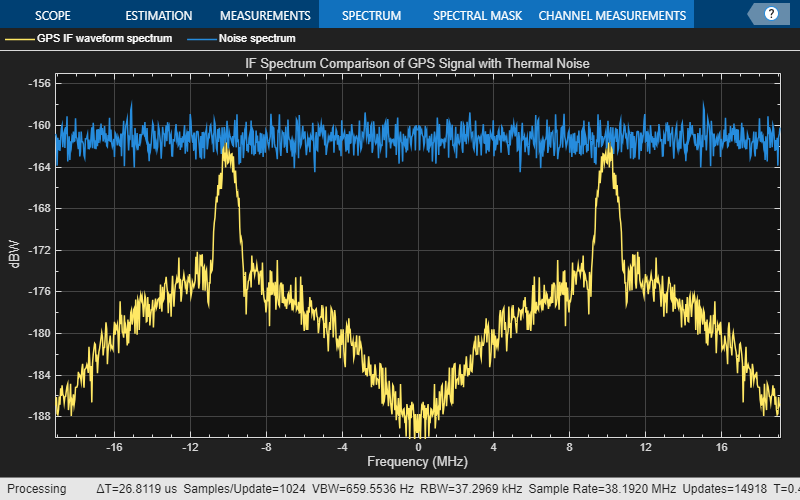

if ShowVisualizations == 1
    ifscope = spectrumAnalyzer(SampleRate = upconvert.IFSampleRate, ...
        PlotAsTwoSidedSpectrum = true, ...
        SpectrumType = "Power", ...
        SpectrumUnits = "dBW", ...
        Title = "IF Spectrum Comparison of GPS Signal with Thermal Noise", ...
        ShowLegend = true, ...
        ChannelNames = ["GPS IF waveform spectrum" "Noise spectrum"], ...
        YLimits = [-190 -155]);
    ifscope([resultsig, noisesig]);
end

Visualize the received signal spectrum. The spectrum appears as if there is only noise. Because the received signal is scaled to have unit power, the spectrum is at unit power noise signal level.

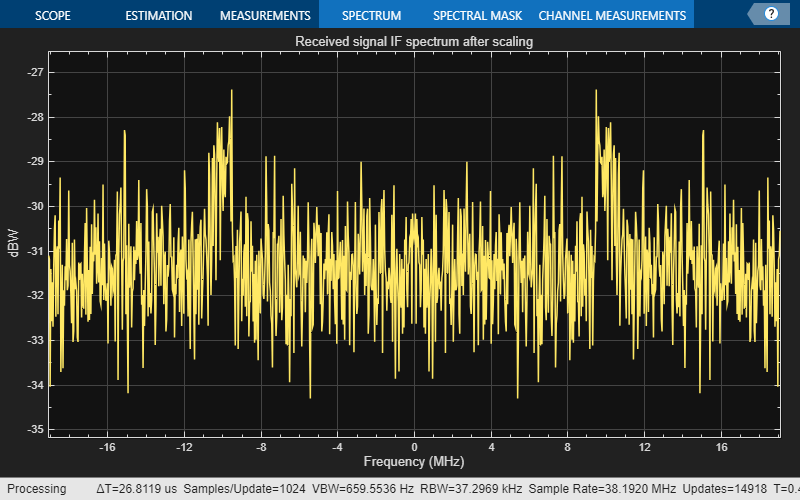

if ShowVisualizations == 1
    rxscope = spectrumAnalyzer(SampleRate = upconvert.IFSampleRate, ...
        PlotAsTwoSidedSpectrum = true, ...
        SpectrumType = "Power", ...
        SpectrumUnits = "dBW", ...
        Title = "Received signal IF spectrum after scaling");
    rxscope(rxwaveform);
end

## Initial Synchronization and Tracking

Typically, a receiver starts up in either of these modes [4]:

- Hot start — The receiver has information about its current location and has almanac information of the available satellites. This kind of startup happens when the receiver momentarily loses track of the visible satellite. In this mode, for a given satellite, initial synchronization is skipped and only tracking is performed.

- Warm start — The receiver knows its own approximate location as it did not move much after the receiver is turned off. Also, the receiver has approximate almanac information. This kind of startup typically happens when the receiver is turned off for few seconds to a few hours and the receiver did not move much after the receiver is turned off. In this mode, the search for all the available satellites is skipped. Initial synchronization for known visible satellites is performed and tracking is done on detected satellites.

- Cold start — The receiver does not have any information of its location before it is turned off and receiver might have traveled anywhere throughout the world. Receiver doesn't have any information about the almanac. All the satellites are searched in the initial synchronization and tracking is performed on the detected satellites.

Cold start takes the longest time to locate itself because there is no known information. The time taken by the receiver to locate itself is known as time to first fix (TTFF). This example assumes the receiver to be in cold start mode in the beginning and starts the search for all the possible 32 GPS satellites. Once the visible satellites are detected, the tracking operates on these satellites. This example does not decode the almanac information and works with the satellites that are detected by initial synchronization.

Initial synchronization module detects all the visible satellites, estimates the coarse Doppler shift, and coarse time offset in the received signal from each satellite [5]. This example transforms the C/A-code into the frequency-domain by using the FFT algorithm and perform multiplication in frequency domain with the signal and then goes back into time-domain by using IFFT. This synchronization is one of the fastest initial synchronization algorithms [5]. The block diagram of this parallel code-phase search algorithm is shown in this figure. Though this figure shows the block diagram for the received IF waveform, the same block works for baseband waveform also (with a difference in the sampling rate and the FFT size).

[image: acquisitionUsingParallelCodeSearch.svg]

To use this parallel-code phase algorithm, first initialize the acquisition object and configure its properties.

initialsync = gnssSignalAcquirer;
initialsync.SampleRate = upconvert.IFSampleRate;
initialsync.IntermediateFrequency = CenterFrequency

initialsync =   gnssSignalAcquirer with properties:

              GNSSSignalType: "GPS C/A"
                  SampleRate: 38192000
       IntermediateFrequency: 10000000
              FrequencyRange: [-10000 10000]
         FrequencyResolution: 500
    DetectionThresholdFactor: 1.9000


The tracking module compensates for the Doppler shift and code phase offset, remaining after initial synchronization. There are three parameters that must be tracked: carrier frequency, carrier phase, and code delay. Each one of these parameters are tracked using the feedback loops. Carrier frequency is tracked using FLL, phase is tracked using PLL, and code phase offset is tracked using DLL. The fundamental structure of any tracking loop (FLL, or PLL, or DLL) is the same and is depicted in the following figure. A combiner combines the incoming signal with that of reference signal generated in the feedback loop. The discriminator finds the error in the incoming signal with that of the reference signal, using the signal generated by the combiner. The tracking loops attempt to reduce this error to zero. This error can be any physical quantity such as frequency in FLL, or phase in PLL, or delay in DLL. This error is processed through a low-pass filter called loop filter. The loop filter reduces the noise in the discriminator output. The loop filter is fundamentally an integrator that accumulates the discriminator output to drive the error (discriminator output) to zero. The other module in the tracking loop is a numerically controlled oscillator (NCO). This is also a simple integrator, which accumulates the output from loop filter [1].

[image: trackingLoopsBasics.svg]

The main role of the loop filter is to filter out the noise from the output of discriminator [1]. This filtering ensures any sudden changes in errors are reflected only after a sufficient amount of convergence time. This phenomenon can be observed in the results of the tracking module shown at the end of this example, where the discriminator output appears to be noisier than the tracking loop output. The amount of noise that must be allowed to be processed by the tracking loop is controlled by loop noise bandwidth (BW). This parameter differs for each tracking loop because if the loop bandwidth is more, then the loop filter allows more noise to pass through the tracking loop, and the convergence is fast. Similarly, a lesser noise bandwidth filter allows less noise to pass through the filter, and the convergence is slow. This table shows typical values used for noise bandwidth for different tracking loops [1]. An important factor for a tracking loop is the loop order. Higher order loops can tolerate sudden changes in the signal but are less stable. More stable lower order loops cannot operate in dynamic environments. This example uses a first order FLL, a second order PLL, and a first order DLL. The following table shows all these parameters for all the three loops used in this example. To configure these values, see the Receiver Configuration.

This figure shows the various interconnections of tracking loops of a GPS receiver. In this figure, $I_p +{\textrm{jQ}}_p$ is the integrated signal from the prompt code, $I_e +{\textrm{jQ}}_e$ is the integrated signal from the half chip early code, and $I_l +{\textrm{jQ}}_l$ is the integrated signal from the half chip late code. Prompt code is the signal that is multiplied by the time synchronized replica of the C/A-code. This time synchronized code is obtained once the lock is established in the loop. Early code is generated by cyclically advancing the prompt code. Late code is generated by cyclically delaying the prompt code by half chip duration. The FLL discriminator uses a four quadrant atan2 discriminator [1], which calculates the frequency offset by evaluating the angle the phasor rotates in a given amount of integration time. The vector formed by $I_p+jQ_p$ is the phasor. If there is frequency offset, then this phasor rotates with an angular velocity. Use this angular velocity to compute the frequency offset. Because the C/A-code is placed on the quadrature branch, if there is a phase offset, then this phasor will not be at a location near to the y-axis. From the angle made by this phase with the y-axis, calculate the phase offset in the phase discriminator. The delay discriminator works on the principle that the correlation of prompt code must always be highest when compared with early or late codes. If the prompt code correlation is not highest, then the delay discriminator generates an appropriate error that corrects the delay in a way that correlation of prompt code is maximum [1].

[image: tracking1.svg]

Carrier and code tracking must happen on the visible satellites. For each satellite, separate tracking loops are necessary. This code initializes several parameters required for tracking. Perform initial synchronization to find and track the visible satellites.

The detected satellite PRN IDs: 11   7  28  20


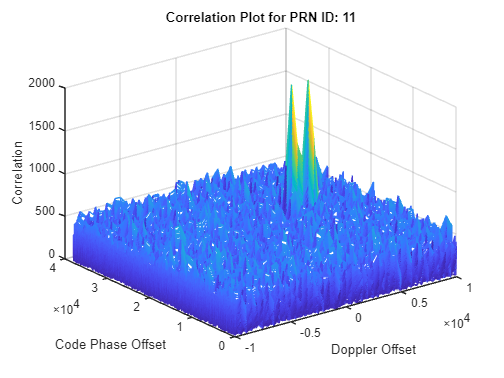

% Consider the data that is 1 millisecond long.
numSamples = SampleRate*IntegrationTime;
[allRxInput,prevSamples] = buffer(rxwaveform,numSamples);
nFrames = size(allRxInput,2);
numdetectsat = 0;
PRNIDsToSearch = 1:32;

for iBuffer = 1:nFrames
    bufferWave = allRxInput(:,iBuffer);

    if iBuffer == 1
        % This example assumes a hot start for all the satellites once initial synchronization is complete
        % Hence, perform initial synchronization only once in this example
        % When decoding the almanac data too, based on the available satellites, initial synchronization can be performed for the visible satellites only
        numSamplesForInitSync = SampleRate*1e-3; % Corresponding to 1 milliseccond
        [y,corrval] = initialsync(bufferWave(1:numSamplesForInitSync),1:32); % Search for all 32 GPS satellites
        PRNIDsToSearch = y(y(:,4).IsDetected==1,1).PRNID.';                  % Get row vector
        doppleroffsets = y(y(:,4).IsDetected==1,2).FrequencyOffset;
        codephoffsets = y(y(:,4).IsDetected==1,3).CodePhaseOffset;

        numdetectsat = length(PRNIDsToSearch);

        disp("The detected satellite PRN IDs: " + num2str(PRNIDsToSearch))
        if ShowVisualizations == 1
            figure;
            mesh(initialsync.FrequencyRange(1):initialsync.FrequencyResolution:initialsync.FrequencyRange(2), ...
                0:size(corrval,1)-1, corrval(:,:,1));
            xlabel("Doppler Offset")
            ylabel("Code Phase Offset")
            zlabel("Correlation")
            msg = "Correlation Plot for PRN ID: " + PRNIDsToSearch(1);
            title(msg)
        end

        % Initialize all the properties which must be accumulated.
        accuph = zeros(nFrames,numdetectsat); % Each column represents data from a satellite
        accufqy = zeros(nFrames,numdetectsat);
        accufqyerr = zeros(nFrames,numdetectsat);
        accupherr = zeros(nFrames,numdetectsat);
        accuintegwave = zeros(nFrames,numdetectsat);
        accudelay = zeros(nFrames,numdetectsat);
        accudelayerr = zeros(nFrames,numdetectsat);

        % Update properties for each tracking loop
        carrierCodeTrack = gnssSignalTracker;
        carrierCodeTrack.SampleRate = SampleRate;
        carrierCodeTrack.IntermediateFrequency = CenterFrequency;
        carrierCodeTrack.PLLNoiseBandwidth = PLLNoiseBandwidth;
        carrierCodeTrack.FLLNoiseBandwidth = FLLNoiseBandwidth;
        carrierCodeTrack.DLLNoiseBandwidth = DLLNoiseBandwidth;
        carrierCodeTrack.IntegrationTime = IntegrationTime;
        carrierCodeTrack.PRNID = PRNIDsToSearch;
        carrierCodeTrack.InitialFrequencyOffset = doppleroffsets;
        carrierCodeTrack.InitialCodePhaseOffset = codephoffsets;
    end

    [integwave,trackinfo] = carrierCodeTrack(bufferWave);

    % Accumulate the values to see the results at the end
    accuintegwave(iBuffer,:) = integwave;
    accufqyerr(iBuffer,:) = trackinfo.FrequencyError;
    accufqy(iBuffer,:) = trackinfo.FrequencyEstimate;
    accupherr(iBuffer,:) = trackinfo.PhaseError;
    accuph(iBuffer,:) = trackinfo.PhaseEstimate;
    accudelayerr(iBuffer,:) = trackinfo.DelayError;
    accudelay(iBuffer,:) = trackinfo.DelayEstimate;
end

trackedSignal = accuintegwave; % Useful for further GPS receiver processing

The following plot shows the tracking loop results. The estimated phase error shows that it (second plot) is not converged until the frequency locked loop is converged (first plot). This behavior is expected because the error in frequency causes an error in phase. Also, the output of PLL and FLL seems to change with time because of the changing Doppler shift with time.

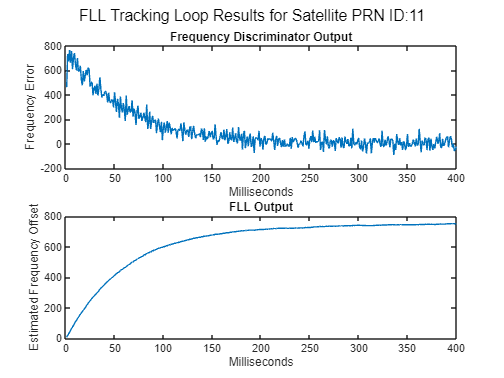

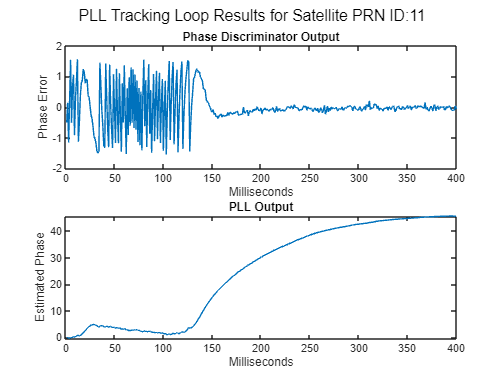

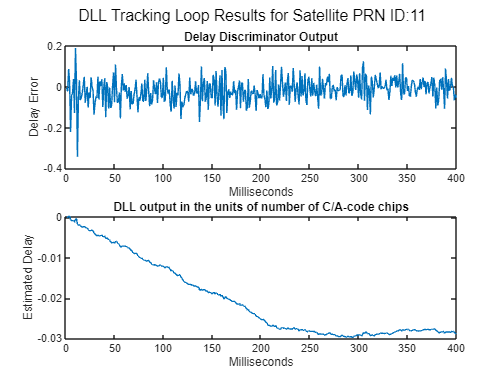

if ShowVisualizations == 1
    % for isat = 1:numdetectsat
    for isat = 1 % See tracking results of all the detected satellites by using above line
        groupTitle = "Tracking Loop Results for Satellite PRN ID:" + PRNIDsToSearch(isat);

        figure

        % Plot the frequency discriminator output
        subplot(2,1,1)
        plot(accufqyerr(:,isat))
        xlabel("Milliseconds")
        ylabel("Frequency Error")
        title("Frequency Discriminator Output")

        % Plot the FLL output
        subplot(2,1,2)
        plot(accufqy(:,isat))
        xlabel("Milliseconds")
        ylabel("Estimated Frequency Offset")
        title("FLL Output")
        sgtitle("FLL " + groupTitle)

        figure

        % Plot the phase discriminator output
        subplot(2,1,1)
        plot(accupherr(:,isat))
        xlabel("Milliseconds")
        ylabel("Phase Error")
        title("Phase Discriminator Output")

        % Plot the PLL output
        subplot(2,1,2)
        plot(accuph(:,isat))
        xlabel("Milliseconds")
        ylabel("Estimated Phase")
        title("PLL Output")
        sgtitle("PLL " + groupTitle)

        figure

        % Plot the delay discriminator output
        subplot(2,1,1)
        plot(accudelayerr(:,isat))
        xlabel("Milliseconds")
        ylabel("Delay Error")
        title("Delay Discriminator Output")

        % Plot the DLL output
        subplot(2,1,2)
        plot(accudelay(:,isat))
        xlabel("Milliseconds")
        ylabel("Estimated Delay")
        title("DLL output in the units of number of C/A-code chips")
        sgtitle("DLL " + groupTitle) 
    end
end

After tracking, plot the constellation of the signal.

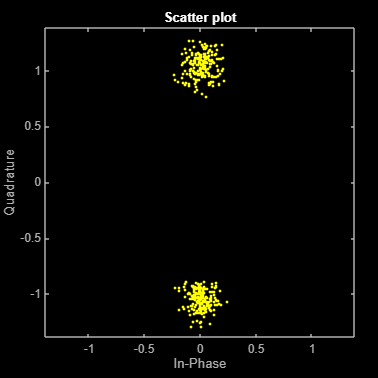

if ShowVisualizations == 1
    demodsamples = accuintegwave(301:end,:)/rms(accuintegwave(:));
    if ~isempty(demodsamples)
        scatterplot(demodsamples(:))
    end
end

## Further Exploration

This example shows the simulation for  four GPS satellites. For a GPS-enabled smart phone, typically 6 GPS satellites are visible at any given point of time. You can increase the number of visible GPS satellites and observe the results. Initialize the Doppler, SNR, and delay appropriately.

This example uses hardcoded values for the delay and Doppler in each satellite signal. You can also model these two parameters as a real GPS satellite using [satellite scenario features](docid:satcom_doccenter#mw_84b41740-e31d-4d8c-901b-21e9ed8de918) in Satellite Communications Toolbox. Using these features, calculate the distance between transmitter and receiver and model the delay either using speed of light or any other delay models. For more information, refer to [End-to-End GPS Legacy Navigation Receiver Using C/A-Code](docid:satcom_ug#mw_e9417f04-eead-4163-bbfe-a0b66ddeda68) example.

The receiver configuration properties in this example are set to optimize for the conditions set in this example. You can update these receiver configuration parameters that suit the conditions you want the example to work. For example, for a much lower SNR than what is used in this example, reduce the noise bandwidth of any loop to any appropriate value that the tracking algorithm works properly. Reducing the noise bandwidth value can help to track the signal properly in high noise and low mobility conditions.

## Appendix

This example uses these data and helper files:

- [gpsAlmanac.txt](matlab:openExample('satcom/GPSReceiverAcquisitionTrackingUsingCACodeExample','supportingFile','gpsAlmanac.txt')) — Almanac data file downloaded from [Navcen](https://www.navcen.uscg.gov/?pageName=currentAlmanac&format=sem-txt) website

- [HelperGPSNAVDataEncode.m](matlab:openExample('satcom/GPSReceiverAcquisitionTrackingUsingCACodeExample','supportingFile','HelperGPSNAVDataEncode.m')) — Encode navigation data into bits from data that is in configuration object

- [HelperGPSNavigationConfig.m](matlab:openExample('satcom/GPSReceiverAcquisitionTrackingUsingCACodeExample','supportingFile','HelperGPSNavigationConfig.m')) — Create configuration object for GPS navigation data

- [HelperGPSUpConvert.m](matlab:openExample('satcom/GPSReceiverAcquisitionTrackingUsingCACodeExample','supportingFile','HelperGPSUpConvert.m')) — Model Doppler shift and up-convert the baseband signal to intermediate frequency

## References

[1] Elliott D. Kaplan and C. Hegarty, eds., *Understanding GPS/GNSS: Principles and Applications*, Third edition, GNSS Technology and Applications Series (Boston ; London: Artech House, 2017).

[2] IS-GPS-200, Rev: L. *NAVSTAR GPS Space Segment/Navigation User Segment Interfaces*. May 14, 2020; Code Ident: 66RP1.

[3] CCSDS 130.11-G-1. Green Book. Issue 1. "SCCC—Summary of Definition and Performance." *Informational Report Concerning Space Data System Standards*. Washington, D.C.: CCSDS, April 2019.

[4] John W. Betz, *Engineering Satellite‐Based Navigation and Timing: Global Navigation Satellite Systems, Signals, and Receivers* (John Wiley & Sons, Ltd, 2015).

[5] K. Borre, ed., *A Software-Defined GPS and Galileo Receiver: A Single-Frequency Approach*, Applied and Numerical Harmonic Analysis (Boston, Mass: Birkhäuser, 2007).

*Copyright 2021-2023 The MathWorks, Inc.*